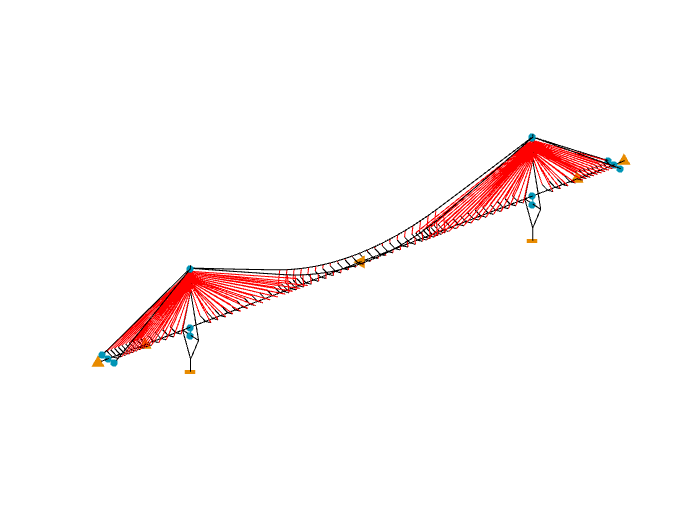

bridgeobj = BridgeObjs(3);
[fig,ax] = bridgeobj.plot();

axis off;
axis equal;
hold(ax,'on');
stayedcables = bridgeobj.findStructureByClass('StayedCable');
hangers = bridgeobj.findStructureByClass('Hanger');
for i=1:length(stayedcables)
    stayedcable = stayedcables{i};
    lines = stayedcable.Line;
    lines.plot('Figure',fig,'Axis',ax,'Color','r');
end

for i=1:length(hangers)
    hanger = hangers{i};
    lines = hanger.Line;
    lines.plot('Figure',fig,'Axis',ax,'Color','r');
end



view([0,-1,0]);

nocable_bridgeobj = BridgeObjs_NoCable(3);

函数或变量 'loadResult' 无法识别。

Load_SelfAnchor_1 = nocable_bridgeobj.LoadList{end-1};
Load_SelfAnchor_2 = nocable_bridgeobj.LoadList{end};
hided_load_name = {Load_SelfAnchor_1.Name,Load_SelfAnchor_2.Name};
fig = figure;
ax = axes;
nocable_bridgeobj.plot('Figure',fig,'Axis',ax,...
                       'HidedLoadName',hided_load_name,...
                       'LoadScale',1e-5);
view([0,-1,0]);
axis off;
axis equal;
hold(ax,'on');

onlycable_bridgeobj = nocable_bridgeobj.getOnlyCableBridge();
onlycable_bridgeobj.plot